# Extract Image Features Using Resnet18

## Load Data

imdsTest = imageDatastore('COVID19_CT_seg_20cases\test','IncludeSubfolders',true,'LabelSource','foldernames');
imdsTrain = imageDatastore('UCSD_combined\train','IncludeSubfolders',true,'LabelSource','foldernames');

## Load Pretrained Network

net = resnet18;
inputSize = net.Layers(1).InputSize;
% analyzeNetwork(net);

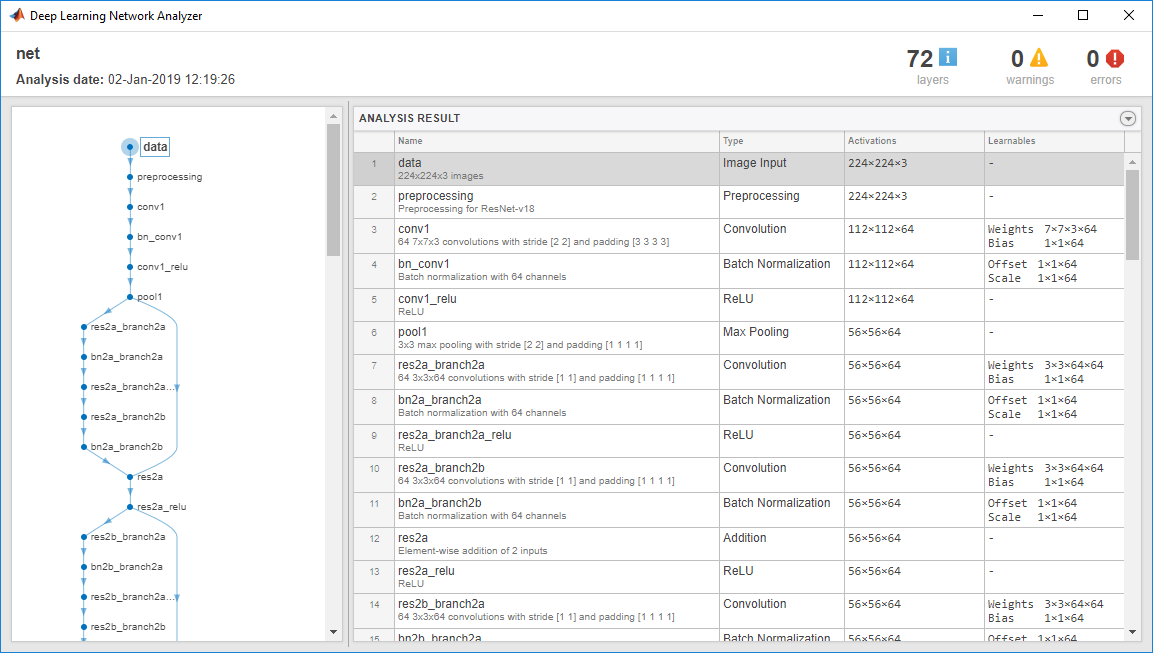

## Extract Image Features

augimdsTrain = augmentedImageDatastore(inputSize,imdsTrain, "ColorPreprocessing","gray2rgb");
augimdsTest = augmentedImageDatastore(inputSize,imdsTest, "ColorPreprocessing","gray2rgb");

% Get layer that feature will be extracted from.
layer = 'res5a';

featuresTrain = activations(net,augimdsTrain,layer,'OutputAs','rows');
featuresTest = activations(net,augimdsTest,layer,'OutputAs','rows');

Extract the class labels from the training and test data.

YTrain = imdsTrain.Labels;
YTest = imdsTest.Labels;

## Fit Image Classifier

Use the features extracted from the training images as predictor variables and fit a multiclass support vector machine (SVM) using `fitcecoc` (Statistics and Machine Learning Toolbox).

t = templateSVM('KernelFunction', 'linear', 'KernelScale','auto', 'Standardize', true);
classifier = fitcecoc(featuresTrain,YTrain,'Learners',t);

## Classify Test Images

Classify the test images using the trained SVM model using the features extracted from the test images.

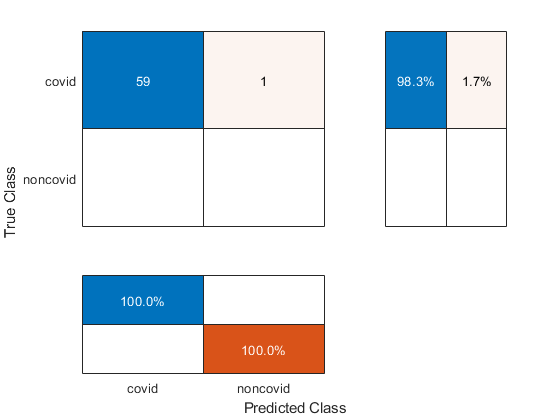

YPred = predict(classifier,featuresTest);

% Calculate accuracy.
accuracy = mean(YPred == YTest);

% Get confusion matrix values.
conf_values = confusionmat(YTest, YPred);

% Get true positive, false negative, false positive
TP = conf_values(1,1);
FN = conf_values(1,2);
FP = conf_values(2,1);
TN = conf_values(2,2);

% Calculate Recall, precision, fscore
Recall = TP /(TP + FN);
if isnan(Recall)
    Recall = 0;
end
% Calculate Precision
Precision = TP / (TP + FP);
if isnan(Precision)
    Precision = 0;
end
% Calculate FScore
FScore = (2*(Precision * Recall)) / (Precision+Recall);
if isnan(FScore)
    FScore = 0;
end

% Create confusion chart.
figure;
conf_values = confusionchart(YTest, YPred,'RowSummary','row-normalized','ColumnSummary','column-normalized');

accuracy

accuracy = 0.9833

FScore

FScore = 0.9916